# Simple Voice Recorder

Records your voice for 10 seconds using your PC's audio input device.

Prepared for EG-247 Signals and Systems by Dr Chris P. Jobling

## Set up audio recorder

recObj = audiorecorder;

## Record some sound

Start speaking: say:

***Hello, My name is [say your name] and this is EG-247/EG-3068 Signals and Systems***

recordblocking(recObj, 10);
disp('End of Recording.');

End of Recording.


% Display meta data
recObj

recObj =   audiorecorder with properties:

       SampleRate: 8000
    BitsPerSample: 8
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 80000
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audiorecorder'


## Play back the recording.

play(recObj);

## Store data in double-precision array.

myRecording = getaudiodata(recObj);

## Plot the waveform.

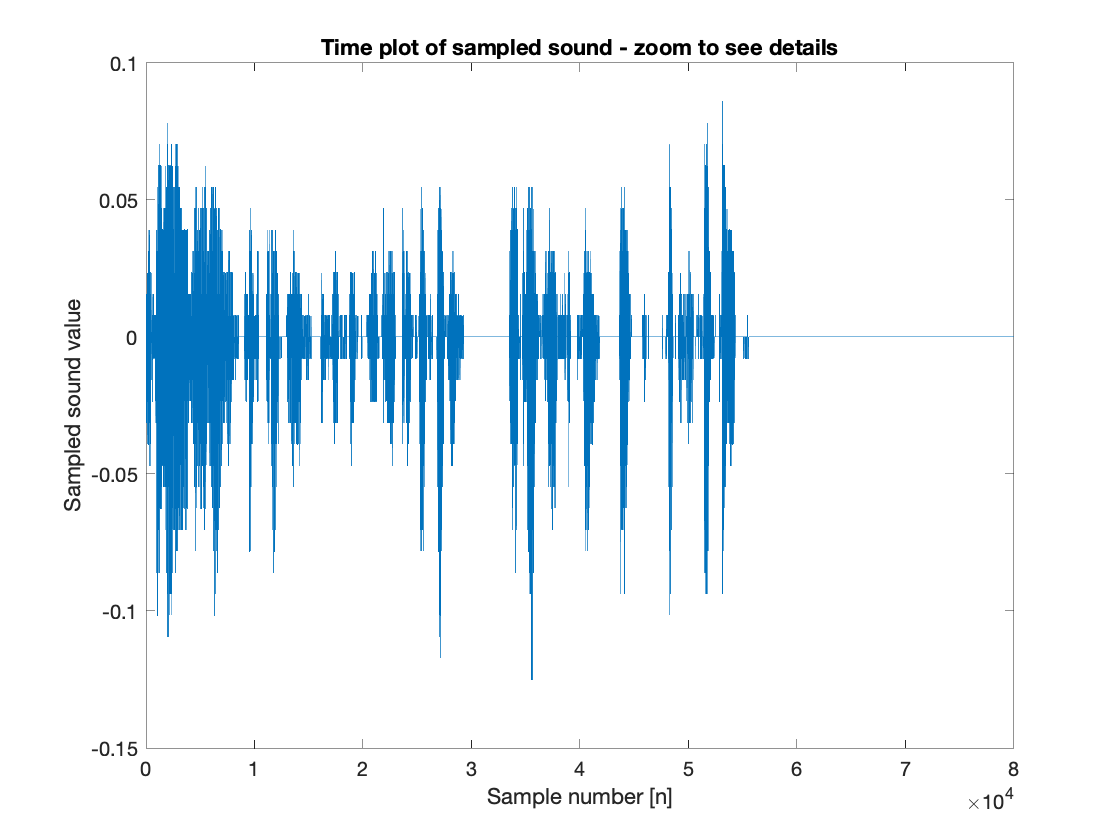

plot(myRecording);
title('Time plot of sampled sound - zoom to see details')
xlabel('Sample number [n]')
ylabel('Sampled sound value')

Plot the samples

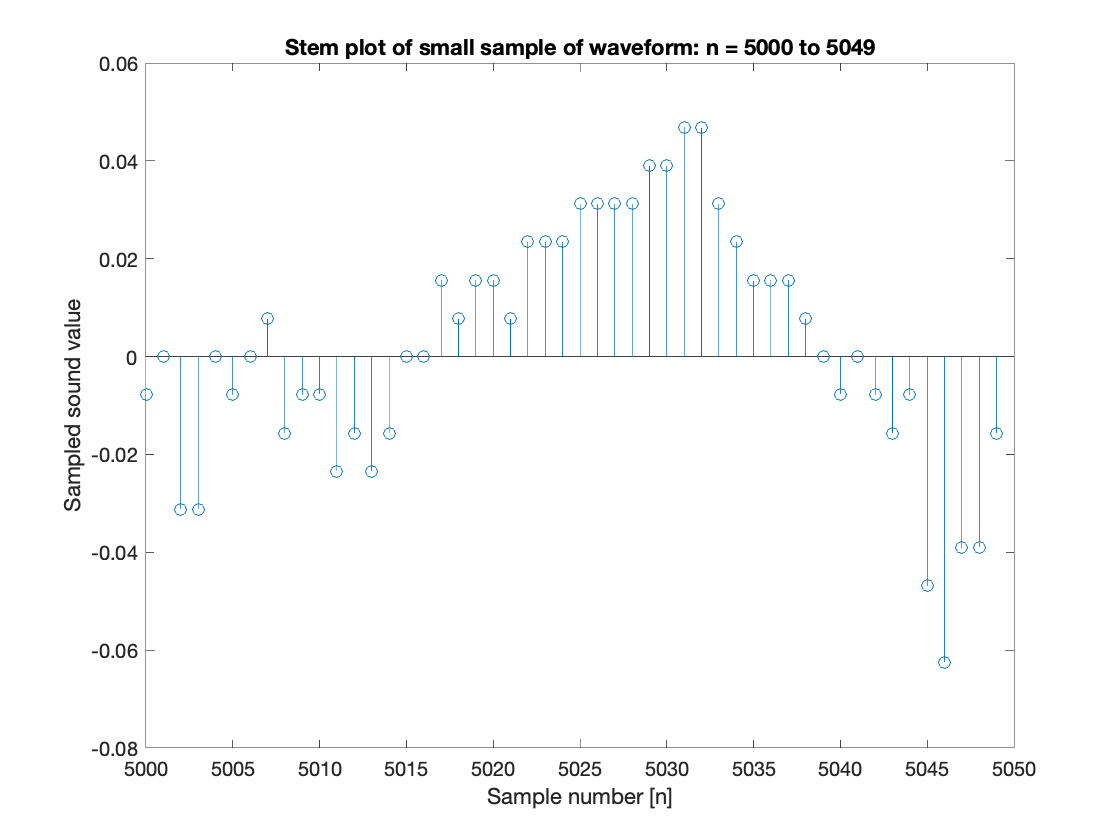

stem([5000:5049],myRecording(5000:5049))
title('Stem plot of small sample of waveform: n = 5000 to 5049')
xlabel('Sample number [n]')
ylabel('Sampled sound value')

## Save the result

Fs = recObj.SampleRate;
audioFile = 'eg-247-message.wav';
audiowrite(audioFile,myRecording,Fs);
disp(['Audiofile Written as: ',audioFile]);

Audiofile Written as: eg-247-message.wav
